## Transmission Zeros, Zero-Pole Cancellation and Sigma Plots

###                                                                - Akash Sharma & Yash Malandkar

The singular value decomposition of a matrix is given by -

$G=\textrm{US}V^T$ where **U** and **V** are orthonormal matrices and represent the output and input directions respectively. **S **is the sigma matrix composed of singular values that represent the output amplitude (in this case, the displacement).

The **G** matrix, in this case, is the transfer matrix at the frequency which corresponds to a set of particular singular values. Since, the maximum singular value of the **S** matrix gives the maximum amplitude of the output, we require the frequency at which this largest singular value is maximized.

### Question 1

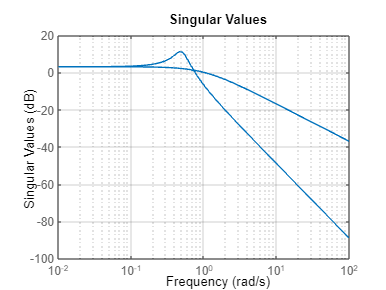

clear all
clc
close all

s = tf('s');

G1 = -0.25/(s^2 + 0.2*s + 0.25);
G2 = 0.25/(s^2 + 0.2*s + 0.25);
G3 = -1/(s+1);
G4 = -1/(s+1);

G = [G1 G2 ; G3 G4];

sigma(G)
grid on

From the plot, we observe that the frequency at which the largest sigma peaks = **0.481 rad/s**.

### Question 2 & 3

G_max = evalfr(G,0.481*i);
[Um,Sm,Vm] = svd(G_max)

Um =   -0.1902 + 0.9817i   0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.9012 + 0.4335i


Sm =     3.6081         0
         0    1.2744


Vm =     0.7071    0.7071
   -0.7071    0.7071



w_cap = Vm(:,1) % input direction

w_cap =     0.7071
   -0.7071


p_cap = Um(:,1) % output direction

p_cap =   -0.1902 + 0.9817i
  -0.0000 + 0.0000i


The maximum gain corresponds to the largest singular value in the **S** matrix and the input and output directions are consequently the first columns of the **V** and **U** matrices respectively. If we take an input direction which is a linear combination of multiple columns of the **V** matrix, it will result in lower gain amplitude. The output direction will also be a linear combination of the columns of the **U** matrix.

### ***Question 4***

We need to compute the maximum displacement of the building to capture the total movement throught the drone.

G_resp = evalfr(G,10*pi*i);  % transfer matrix for the 10pi frequency
syms t

w = [2 ; -3*i]*exp(i*10*pi*t); % input vector
p = G_resp*w;

time = linspace(1,10,10^4);
pn = double(subs(p(1,:),t,time));
pe = double(subs(p(2,:),t,time));

pn_max = max(imag(pn))

pn_max = 9.1351e-04

pe_max = max(imag(pe))

pe_max = 0.1147

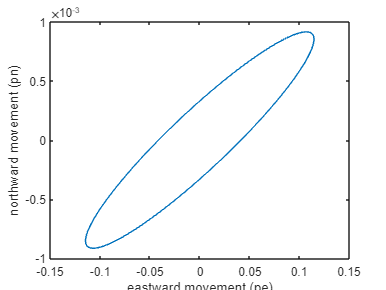


p_max = sqrt(pn_max^2 + pe_max^2);

plot(imag(pe),imag(pn)) % motion of the building
xlabel('eastward movement (pe)')
ylabel('northward movement (pn)')


h = p_max/tand(60/2)

h = 0.1987

After the maximum displacement p_max is found, the minimum height required is computed given the drone's viewing angle = 60deg to be **0.1987m**.